# `Ch3_7_1`

`求`16`点序列`$x\left(n\right)$`的频谱及补零到`32`和`64`点后的频谱。`

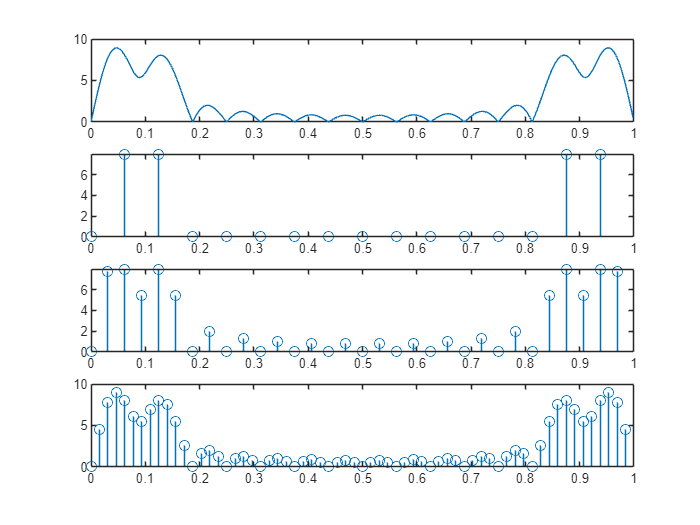

N1 = 16;
n = 0:15;
x = sin(2*pi*n/N1) + cos(4*pi*n/N1);

N2 = 32;
n2 = 0:31;
x2 = [x, zeros(1,16)]; 

N3 = 64;
n3 = 0:63;
x3 = [x, zeros(1,48)]; 

L1 = 0:15;
dft_16 = fft(x,16);
L2 = 0:31;
dft_32 = fft(x2,32);
L3 = 0:63;
dft_64 = fft(x3,64);

nx = 0:15;
K = 512;
dw = 2*pi/K;
k = 0:511;
X = x*exp(1i*dw*nx'*k);
subplot(4,1,1); plot(k*dw/(2*pi),abs(X));
subplot(4,1,2); stem(L1/N1,abs(dft_16));
subplot(4,1,3); stem(L2/32,abs(dft_32));
subplot(4,1,4); stem(L3/64,abs(dft_64));